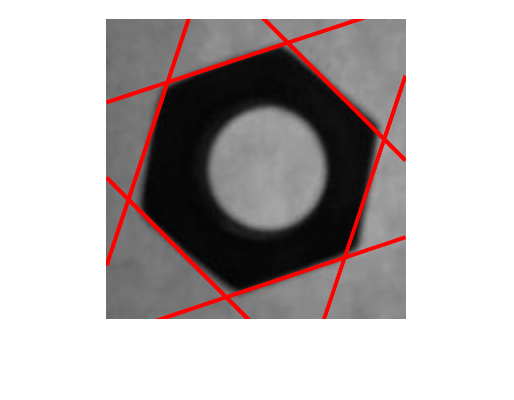

%%% 1.b

clc
clear

img = imread('HW2.jpg'); 
img_gray = rgb2gray(img); 
img_BW = imbinarize(img_gray); 
img_BW = imcomplement(img_BW); 
img_edge = edge(img_BW, 'canny');
B = bwboundaries(img_edge,'noholes');
B = B{1}; 


[gy, gx] = imgradientxy(img_edge);
A= zeros(800,800);

for i=1:size(B,1)
        y=B(i,1);
        x=B(i,2);

        if gx(x,y)~=0 && gy(x,y)~=0
            v=(x*gx(x,y)+y*gy(x,y))./(gx(x,y)^2 + gy(x,y)^2);
            x0=round(v*gx(x,y));
            y0=round(v*gy(x,y));
            A(x0+100,y0+100)=A(x0+100,y0+100)+1;
        end
        

end

figure;
imshow(img_gray);
hold on;

peak = houghpeaks(A,8,"Threshold",1);

peak(7,:)=[];
peak(6,:)=[];
for i=1:6

    pointx0=peak(i,1) - 100;
    pointy0=peak(i,2) - 100;

    slope=-pointx0/pointy0;
    b=pointy0-pointx0.*slope;
    xx = 1:300;
    yy=xx.*slope + b;

    plot(xx,yy, 'Color', 'r', 'LineWidth', 2);

end

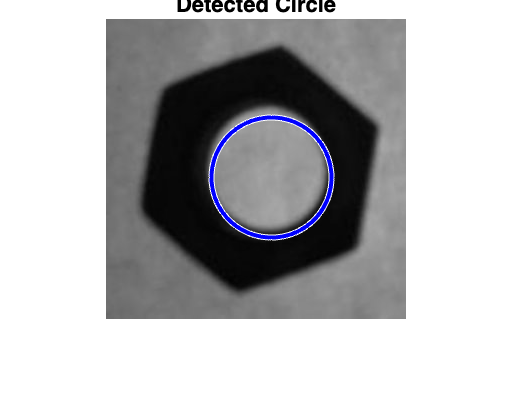

%%% 1.c 

clear;
close all
image=imread('HW2.jpg');
image_bw=rgb2gray(image);
img_BW = imbinarize(image_bw); 
img_BW = imcomplement(img_BW); 
edge=edge(img_BW,'canny');

B = bwboundaries(edge,'holes');
B = B{2}; 


 
R=1:1:70;
A2=zeros(size(edge,1),size(edge,2),size(R,2));
[Gy,Gx]=imgradientxy(edge);


for k=1:size(R,2)
    for i=1:size(B,1)
           x=B(i,2);
           y=B(i,1);
           if Gx(x,y)~=0 && Gy(x,y)~=0
                xc=round(x-R(k)*Gx(x,y)/sqrt(Gx(x,y)^2+Gy(x,y)^2)); 
                yc=round(y-R(k)*Gy(x,y)/sqrt(Gx(x,y)^2+Gy(x,y)^2)); 
                if xc>0 && xc<=size(edge,1) && yc>0 && yc<=size(edge,2) 
                    A2(xc,yc,k)=A2(xc,yc,k)+1; 
                end
           end
    end
end

peak = houghpeaks(A2(:,:,1),1);
xc = peak(1,1)+50;
yc = peak(1,2)+50;
R = 60;

figure 
imshow(image_bw);
hold on

viscircles([xc, yc], R, 'EdgeColor', 'b');
title('Detected Circle');

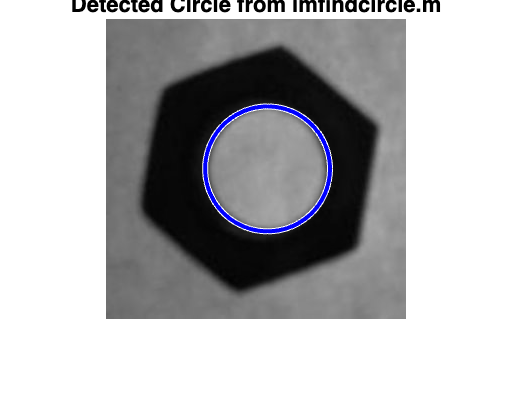

clear 
clc

image = imread('HW2.jpg');
grayImage = rgb2gray(image);
img_BW = imbinarize(grayImage); 
img_BW = imcomplement(img_BW); 
edgeImage = edge(img_BW, 'Canny');

minRadius = 10;
maxRadius = 100;
[centers, radii, ~] = imfindcircles(edgeImage, [minRadius, maxRadius]);

[~, idx] = max(radii);
x0 = centers(idx, 1);
y0 = centers(idx, 2);
r = radii(idx);

imshow(grayImage);
hold on;
viscircles([x0, y0], r, 'EdgeColor', 'b');
title('Detected Circle from imfindcircle.m');
hold off;

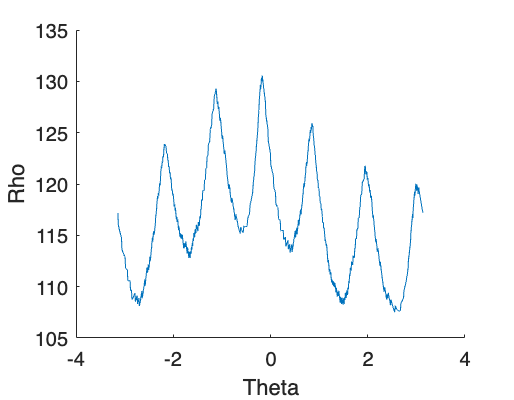


%%% 2.a


% https://github.com/CaiSean/Machine-Vision-ME6406/tree/master/Hough-Transform%20Example%20Code
clc
clear
clf

im= imread('HW2.jpg');
im1= rgb2gray(im);
img_BW = imbinarize(im1); 
img_BW = imcomplement(img_BW); 
im = edge(img_BW);


B = bwboundaries(im,'holes');
B = B{1}; 
xall=B(:,1);
yall=B(:,2);
[row,col]=size(im);
A=zeros(row,col);
s = regionprops(im,'Area', 'centroid');
centroids = cat(1, s.Centroid);

reference= centroids;
yc=reference(1,1);
xc=reference(1,2);
hold on
r=[];
t=[];
x=[];
y=[];


for i=1:size(B,1)
          x=B(i,2);
          y=B(i,1);
          rho = sqrt((x-xc).^2 + (y-yc).^2);
          theta= atan2((y-yc),(x-xc));
          t = [t theta];
          r=[r rho];

         
    
end
t = sort(t);

plot(t,r);
xlabel('Theta');
ylabel('Rho');
hold off

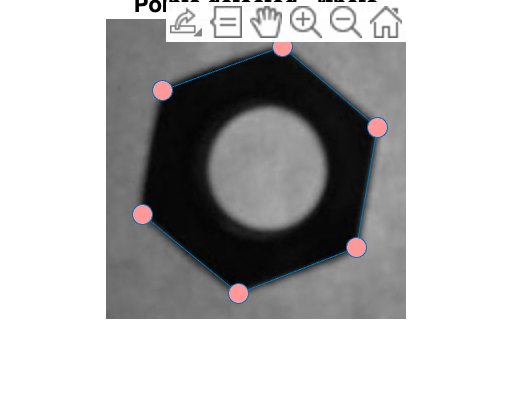


[~,locs]= findpeaks(r,'MinPeakDistance',80);

figure 
imshow(im1)
hold on
plot( yall(locs),xall(locs),'-o','MarkerSize', 10,'MarkerFaceColor',[1 .6 .6]);
title('Points detected - rtheta')
hold off

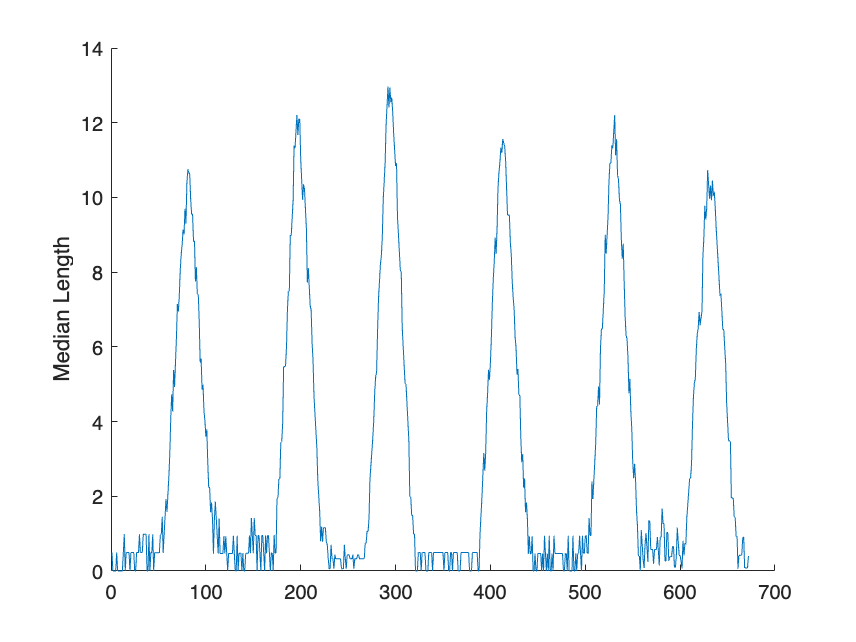

%%% 2.b

im= imread('HW2.jpg');
im= rgb2gray(im);
bwImg=imbinarize(im,0.2);
bwImg=imcomplement(bwImg);

B= bwboundaries(bwImg);
xall=B{1}(:,1);
yall=B{1}(:,2);
x=[xall;xall]';
y=[yall;yall]';
n=25;
Dist=[];
clf
hold on
for i=1:(size(x,2)/2)
    x0=x(i+n);
    x1=x(i);
    x2=x(i+2*n);
    y0=y(i+n);
    y1=y(i);
    y2=y(i+2*n);
    d= abs(((y2-y1)*x0 - (x2-x1)*y0 +x2*y1- y2*x1)/sqrt((y2-y1)^2+(x2-x1)^2));
    Dist=[Dist d];
end
clf

hold on
plot(1:size(x,2)/2,Dist);
ylabel('Median Length')
hold off

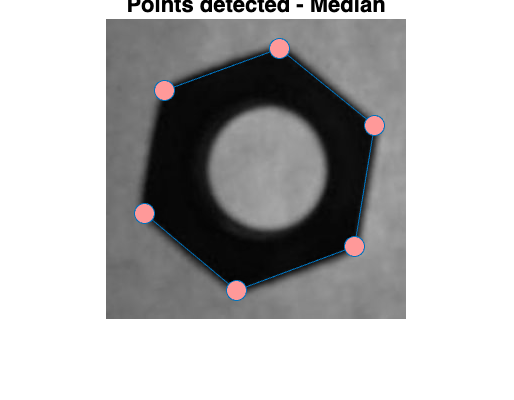


[~,locs]= findpeaks(Dist,'MinPeakDistance',60);
locs(1)=[];
locs= locs+n;
figure 
imshow(im)
hold on
plot( yall(locs),xall(locs),'-o','MarkerSize', 10,'MarkerFaceColor',[1 .6 .6]);
title('Points detected - Median')
hold off

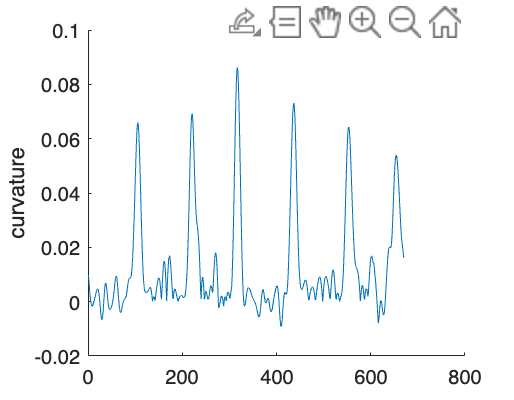

%%% 2.c

im= imread('HW2.jpg');
im= rgb2gray(im);
bwImg= imbinarize(im);
bwImg= imcomplement(bwImg);
B = bwboundaries(bwImg,'noholes');
x=B{1}(:,2);
y=B{1}(:,1);
x=[x;x];
y=[y;y];
n=length(x);
s=linspace(-n/2,n/2,n);
sigma=5;
g0=1/sqrt(2*pi*sigma^2)*exp(-s.^2/(2*sigma^2));
g=[g0 g0]';
x=conv(x,g,'same');
x=x(1:round(end/2));
y=conv(y,g,'same');
y=y(1:round(end/2));
Xd = diff(x);
Yd = diff(y);
Xdd=diff(diff(x));
Ydd=diff(diff(y));
xv=[];
yv=[];
for i=1:length(Xdd)
    xv=[xv x];
    yv=[yv y];
    K(i)=abs(Xd(i)*Ydd(i))-(Xdd(i)*Yd(i));
end

clf

hold on
plot(1:length(K(1:end)),K(1:end));
ylabel('curvature');
hold off

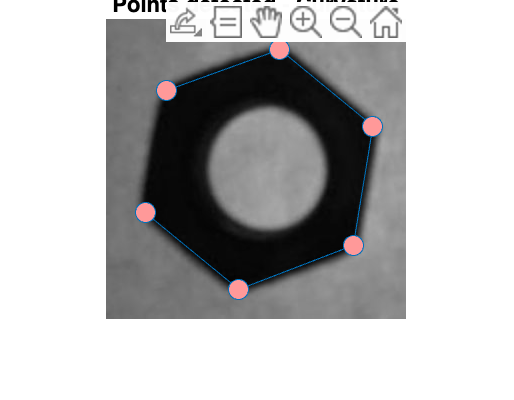

[peaks,locs]= findpeaks(K,'MinPeakDistance',80);
locs(1)=[];

figure 
imshow(im)
hold on
plot( xv(locs),yv(locs),'-o','MarkerSize', 10,'MarkerFaceColor',[1 .6 .6]);
title('Points detected - Curvature')
hold off

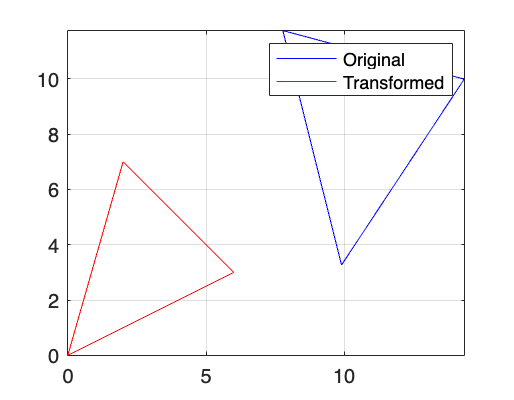

%%% 3.a

clear
clc

k=1.2;
theta=30;
theta_r= pi/6;
Xd=8;
Yd=5;

x0=[0 6 2];
y0=[0 3 7];
Xc=(x0(1)+x0(2)+x0(3))/3;
Yc=(y0(1)+y0(2)+y0(3))/3;
x = x0-Xc;
y = y0-Yc;


q1=k.*cos(theta_r);
q2=k.*sin(theta_r);
q3=Xc+Xd;
q4=Yc+Yd;
Q=[q1;q2;q3;q4];
R=[];

A=[x(1) -y(1) 1 0;y(1) x(1) 0 1;
   x(2) -y(2) 1 0;y(2) x(2) 0 1;
   x(3) -y(3) 1 0;y(3) x(3) 0 1];


R1 = A*Q;


cols=length(R1)/2;
R=reshape(R1,[2,cols]);
x1 = R(1,:);
y1 = R(2,:);
clf
plot([x1,R(1,1)], [y1,R(2,1)], 'b-'); 
grid on
hold on

plot([x0,x0(1)], [y0,y0(1)], 'r-');
legend('Original','Transformed')
hold off;
axis equal;

%%% 3.b

Qt = (A'*A)^-1 *A'*R1;
kd_ = sqrt(Qt(1)^2 + Qt(2)^2)

kd_ = 1.2000

theta_ = atan(Qt(2)/Qt(1))

theta_ = 0.5236

xd_ = Qt(3)-Xc

xd_ = 8

yd_ = Qt(4)-Yc

yd_ = 5

%%% 3.c

clear 
clc

x=[2 5 5 4 1];
y=[1 2 4 5 3];
pointst = [9.697 6.96; 8.566 8.091; 6.869 5.263];

points = [2 1; 5 2; 5 4; 4 5; 1 3];

xt=[9.697 8.566 6.869];
yt=[6.96 8.091 5.263];

% Determine the number of points
numPoints = size(points, 1);

% Define the number of points in each triangle (3 for triangles)
numPointsInTriangle = 3;

% Initialize a matrix to store all possible combinations of points
combinations = nchoosek(1:numPoints, numPointsInTriangle);
Et = inf;
Et1 = inf;
temp = [];
% Iterate through all combinations and form triangles
for i = 1:size(combinations, 1)
    E=0;
    % Get the indices of the points for the current combination
    triangleIndices = combinations(i, :);
    
    % Extract the coordinates of the points for the current triangle
    trianglePoints = points(triangleIndices, :);
    temp = [temp trianglePoints];
    %[xc, yc] = centroid(trianglePoints);
    xc = mean(trianglePoints(:,1));
    yc = mean(trianglePoints(:,2));
    A=[pointst(1,1)-xc -pointst(1,2)-yc 1 0; pointst(1,2)-yc  pointst(1,1)-xc 0 1;
       pointst(2,1)-xc -pointst(2,2)-yc 1 0; pointst(2,2)-yc  pointst(2,1)-xc 0 1;
       pointst(3,1)-xc -pointst(3,2)-yc 1 0; pointst(3,2)-yc  pointst(3,1)-xc 0 1];
    
    R = [trianglePoints(1,1); trianglePoints(1,2);
         trianglePoints(2,1); trianglePoints(2,2);
         trianglePoints(3,1); trianglePoints(3,2);];
    Q=pinv(A)*R;
    E1 = atan((yc-trianglePoints(:,2))/(xc-trianglePoints(:,1))) - atan((yc-pointst(:,2))/(xc-pointst(:,1)));
    E1 = sum(E1(:,1));
    for i1=1:3
        hold = sqrt((pointst(i1,1)-trianglePoints(i1,1)).^2 + (pointst(i1,2)-trianglePoints(i1,2)).^2 );
        E = E+hold;
    end
    E;
    %E = sum(sqrt((trianglePoints(:,1)-pointst(:,1)).^2 + (trianglePoints(:,2)-pointst(:,2)).^2 ))
    if E < Et %&& E1 < Et1
        Et=E;
        Et1 =E1;
        tp = points(combinations(i+1, :), :);
    end

end

xc = mean(tp(:,1));
yc = mean(tp(:,2));
 A=[pointst(1,1)-xc -pointst(1,2)-yc 1 0; pointst(1,2)-yc  pointst(1,1)-xc 0 1;
    pointst(2,1)-xc -pointst(2,2)-yc 1 0; pointst(2,2)-yc  pointst(2,1)-xc 0 1;
    pointst(3,1)-xc -pointst(3,2)-yc 1 0; pointst(3,2)-yc  pointst(3,1)-xc 0 1];
    
R = [tp(1,1); tp(1,2);
     tp(2,1); tp(2,2);
     tp(3,1); tp(3,2);];

Q=pinv(A)*R;
kd_ = sqrt(Q(1)^2 + Q(2)^2)

kd_ = 1.2502

theta_ = atan(Q(2)/Q(1))

theta_ = -0.7854

xd_ = Q(3)-xc

xd_ = -12.8022

yd_ = Q(4)-xc

yd_ = 0.1637

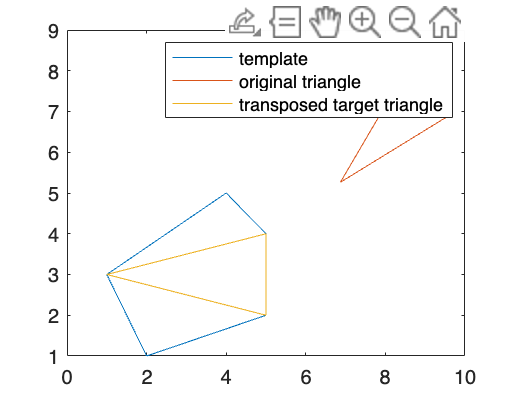



A1=[points(1,1)-xc -points(1,2)-yc 1 0; points(1,2)-yc  points(1,1)-xc 0 1;
   points(2,1)-xc -points(2,2)-yc 1 0; points(2,2)-yc  points(2,1)-xc 0 1;
   points(3,1)-xc -points(3,2)-yc 1 0; points(3,2)-yc  points(3,1)-xc 0 1;
   points(4,1)-xc -points(4,2)-yc 1 0; points(4,2)-yc  points(4,1)-xc 0 1;
   points(5,1)-xc -points(5,2)-yc 1 0; points(5,2)-yc  points(5,1)-xc 0 1];

R1 = A*Q;
cols=length(R1)/2;
R=reshape(R1,[2,cols]);
x1 = R(1,:);
y1 = R(2,:);
clf

x11 = points(:,1);
y11 = points(:,2);
plot([x11',points(1,1),],[y11',points(1,2),]) % template
hold on
plot([xt,xt(1)],[yt,yt(1)]); % original triangle
hold on

plot([x1,R(1,1)], [y1,R(2,1)]); % transposed target triangel

legend('template','original triangle','transposed target triangle')